# Tarea 4C: Análisis y síntesis LPC 

## Consideraremos los ficheros '*test_period_70'*, '*tvg_home_8khz'* y '*tvg_muller_8khz'*. El primero es un fichero de test obtenido como respuesta de un filtro IIR a una entrada consistente en un tren de deltas con periodo 70 muestras.

## Procesaremos cada fichero completo con las funciones syslpc y syslpc_vqq (con VQLSF), y guardaremos en variables separadas las señales originales y sus respectivos errores de predicción. 

## Para cada fichero representad las siguientes figuras que contendrán tres gráficas (subplot): 

-   Señal test_period_70 , error de predicción obtenido con syslpc_vqq y error de predicción obtenido con syslpc en el tramo de la muestra 1000 a la 2000.

-  Lo mismo para tvg_home_8khz, representando el tramo 13500:14500.

- Repetid para tvg_muller_8khz en el tramo 8500:9500. 

#### Comentad razonadamente los resultados obtenidos en cada una de las gráficas. ¿Cómo afecta la cuantificación de los coeficientes de los filtros?

load ('VQParametros.mat','VQLSF');

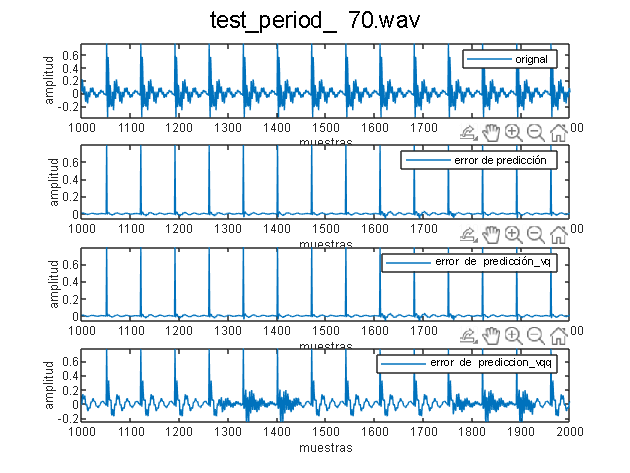

% LE AÑADO SYSLPC_VQ PARA TENER LAS 3 FUNCIONES JUNTAS
[test,fs] = audioread('test_period_70.wav');
test_recort=test(1000:2000);

p=10;
N=160;
Lframe = ones(1,N); 
[recons_test, error_test] = syslpc(test,Lframe,p);
[recons_test_vqq, error_test_vqq] = syslpc_vqq(test,Lframe,10,VQLSF,'LSF');
[recons_test_vq, error_test_vq] = syslpc_vq(test,Lframe,10,VQLSF,'LSF');

error_test_vqq = error_test_vqq(1000:2000);
error_test_d=error_test(1000:2000);
error_test_vq = error_test_vq(1000:2000);
figure(1)
subplot(4, 1, 1); % Primera gráfica
plot(1000:2000, test_recort);
legend('orignal');
xlabel('muestras');
ylabel('amplitud');
axis tight;

subplot(4,1,2);
plot(1000:2000,error_test_d);
xlabel('muestras');
ylabel('amplitud');
legend('error de predicción');
axis tight;

subplot(4,1,3);
plot(1000:2000,error_test_vq);
xlabel('muestras');
ylabel('amplitud');
legend('error de predicción\_vq');
axis tight;

subplot(4,1,4);
plot(1000:2000,error_test_vqq);
xlabel('muestras');
ylabel('amplitud');
legend('error de prediccion\_vqq');
axis tight;
sgtitle('test\_period\_ 70.wav');

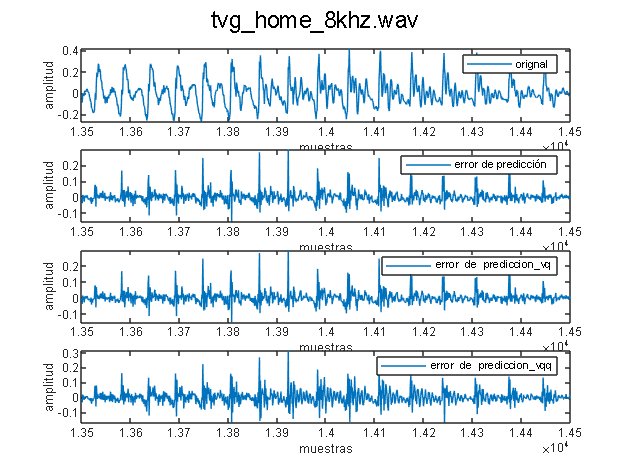

[tvg,fs] = audioread('tvg_home_8khz.wav');
tvg_recort= tvg(13500:14500);

p=10;
N=160;
Lframe = ones(1,N); 
[recons_tvg, error_tvg] = syslpc(tvg,Lframe,p);
[recons_tvg_vqq, error_tvg_vqq] = syslpc_vqq(tvg,Lframe,10,VQLSF,'LSF');
[recons_tvg_vq, error_tvg_vq] = syslpc_vq(tvg,Lframe,10,VQLSF,'LSF');

error_tvg_vqq = error_tvg_vqq(13500:14500);
error_tvg_vq = error_tvg_vq(13500:14500);
error_tvg=error_tvg(13500:14500);

figure(2)
subplot(4, 1, 1); % Segunda gráfica
plot(13500:14500, tvg_recort);
xlabel('muestras');
ylabel('amplitud');
legend('orignal');
axis tight;

subplot(4,1,2);
plot(13500:14500, error_tvg);
xlabel('muestras');
ylabel('amplitud');
axis tight;
legend('error de predicción');

subplot(4,1,3);
plot(13500:14500, error_tvg_vq);
axis tight;
xlabel('muestras');
ylabel('amplitud');
legend('error de prediccion\_vq');

subplot(4,1,4);
plot(13500:14500, error_tvg_vqq);
axis tight;
sgtitle('tvg\_home\_8khz.wav');
xlabel('muestras');
ylabel('amplitud');
legend('error de prediccion\_vqq');

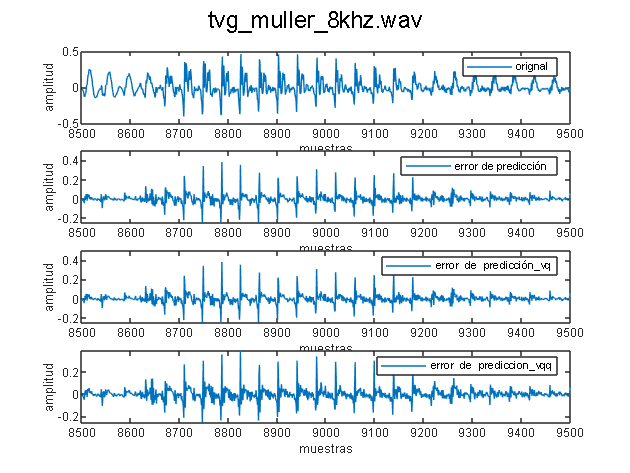

[muller,fs] = audioread('tvg_muller_8khz.wav');
muller_recort= muller(8500:9500);

p=10;
N=160;
Lframe = ones(1,N); 
[recons_muller, error_muller] = syslpc(muller,Lframe,p);
[recons_muller_vqq, error_muller_vqq] = syslpc_vqq(muller,Lframe,10,VQLSF,'LSF');
[recons_muller_vq, error_muller_vq] = syslpc_vq(muller,Lframe,10,VQLSF,'LSF');

error_muller_vqq = error_muller_vqq(8500:9500);
error_muller_vq = error_muller_vq(8500:9500);
error_muller=error_muller(8500:9500);

figure(3)
subplot(4, 1, 1); % Tercera gráfica
plot(8500:9500, muller_recort);
xlabel('muestras');
ylabel('amplitud');
legend('orignal');

subplot(4,1,2);
plot(8500:9500, error_muller);
xlabel('muestras');
ylabel('amplitud');
legend('error de predicción');

subplot(4,1,3);
plot(8500:9500, error_muller_vq);
xlabel('muestras');
ylabel('amplitud');
legend('error de predicción\_vq');

subplot(4,1,4);
plot(8500:9500, error_muller_vqq);
axis tight;
sgtitle('tvg\_muller\_8khz.wav');

xlabel('muestras');
ylabel('amplitud');
legend('error de prediccion\_vqq');

%sgtitle('sysplc y syslpc\_vqq, N=251, p=10');